%calculating the mean first passage time analytically/numerically 
%to investigate optimum position of 1 mismatch from perspective of DNA/RNA
%toehold exchange including spontaneous incumbent and invader dissociation 

b = 20 %define branch migration domain length

b = 20

g = 6 %define invader toehold length

g = 6

g2 = 5 %define incumbent toehold length 

g2 = 5


bg2 = b + g2 %define branch migration domain + incumbent toehold length 

bg2 = 25


R = 1.987/1000 %universal rate constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -0.4*R*temp

dGrd = -0.2370

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant 
k_bp = 5.4*10^7

k_bp = 54000000

DNA_RNA_k_eff = zeros(1,20)

DNA_RNA_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 20)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 20)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


DNA_RNA_k_eff_perf = zeros(1, 20)

DNA_RNA_k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 20)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 20)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through mismatch positions 
for m = 1:20
    m
    
    %loop through states prior to mismatch (in branch migration domain) and
    %define free energy
    for state = 1:m-1
        dGbox_avr(m, state) = - R*temp*log(exp(-((-dGbp-dGrd)*(m - state) + (m)*-dGrd + dGp)/(R*temp)) + exp(-(dGmm+(m-state)*(dGrd) + (m)*-dGrd + dGp)/(R*temp))) 
    end
    
    %define free energy of all states in the branch migration domain 
    dGbox_avr(m, 1:m) = horzcat(dGbox_avr(m, 1:m-1), dGp - (m)*dGrd)

    %define free energy of final state in invader toehold 
    dGboxC1 = -R*temp*log(exp(-((-dGbp - dGrd)*(m-0) + (m)*-dGrd + dGp)/(R*temp)) + exp(-(dGmm)/(R*temp)))
    
    trans_state = (-dGbp - dGrd)*(b +g2-1)
    react_coord = zeros(1, b-1)
    %loop through states prior to mismatch and define free energy for
    %incumbent dissociation
    for state = 1:m-1
        react_coord(state) = -R*temp*log(exp(-(state*(-dGbp-dGrd) + dGmm)/(R*temp)) + exp(-(state*(-dGbp-dGrd))/(R*temp)))
    end
    %loop through states after mismatch and define free energy for
    %incumbent dissociation 
    for state = m:b-1
        react_coord(state) = state*(-dGbp-dGrd)
    end
    react_coord = flip(react_coord);
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
   
    k_C1fm = k_bp * exp(-(dGbox_avr(m,1) - dGboxC1 + dGbm)/(R*temp))
    k_Cf = k_bp * exp(-(dGbm - dGrd)/(R*temp))

    %if m == b
        %k_Cfbm = zeros(1, m-2)
        %for state = 2:m-1 
            %k_Cfbm(state - 1) = k_bp * exp(-(dGbox_avr(m, state) - dGbox_avr(m, state - 1) + dGbm)/(R*temp))
        %end
        %k_Cfbm(m-1) = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    %else
        k_Cfbm = zeros(1, m-2)
        for state = 2:m 
            k_Cfbm(state - 1) = k_bp * exp(-(dGbox_avr(m, state) - dGbox_avr(m, state - 1) + dGbm)/(R*temp))
        end
    %end 
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    %if m == b
        %k_DC = k_bp * exp(-(dGbm + dGbox_avr(m, m-1) - dGbox_avr(m, m) + dGp)/(R*temp))
    %else 
        k_DC = k_bp * exp(-(dGbm + dGp)/(R*temp))
    %end
    k_DEij = k_bp * exp((dGbp + dGrd)/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp *exp((dGbp + dGrd)/(R*temp))
    k_FE = 0
    k_FF = 1    
    
    %create arrays of forward and reverse transition rates for
    %mismatch-free system
    Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %define spontaneous incumbent dissociation rates for mismatch-free
    %system
    Koff_perf = [repmat(0, [1, g2+1])]; 
    for n = g2+1:bg2-1
        Koff_perf = horzcat(Koff_perf, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
    end
    Koff_perf = horzcat(Koff_perf, [repmat(0, [1, g+1])])
        
    if g == 1
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_B1A, k_AA]
        
        %define spontaneous incumbent dissociation rates for mismatch system
        Koff = [repmat(0, [1, g2+1])];
        for n = 1:b-1
            Koff = horzcat(Koff, [k_bp*exp(-(-dGbp - dGrd)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
        end
        Koff = horzcat(Koff, [0, 0])
        
        %define spontaneous invader dissociation rates
        Koff_inv = [repmat(0, [1, g2+1])];
        for n = b+g-1:-1:g+1
            Koff_inv = horzcat(Koff_inv, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff_inv = horzcat(Koff_inv, [0, 0])
           
    else
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-m]), flip(k_Cfbm), k_C1fm, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
        %define spontaneous incumbent dissociation rates for mismatch
        %system
        Koff = [repmat(0, [1, g2+1])]; 
        for n = 1:b-1
            Koff = horzcat(Koff, [k_bp*exp(-(-dGbp - dGrd)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
        %define spontaneous invader dissociation rates
        Koff_inv = [repmat(0, [1, g2+1])];
        for n = b+g-1:-1:g+1
            Koff_inv = horzcat(Koff_inv, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff_inv = horzcat(Koff_inv, [repmat(0, [1, g+1])])
    end
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    j_cycle = zeros(1,numel(Kf));
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
    
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + (Koff(Pn) + Koff_inv(Pn)) * Pn_jN_1(Pn);
        j_cycle(Pn) = Pn_jN_1(Pn)*Koff_inv(Pn);
    end
    
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    j_cycle_perf = zeros(1,numel(Kf_perf));
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
        
    %calculate flux between each state for mismatch-free system
    for Pn = 2:numel(Kf_perf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + (Koff_perf(Pn) + Koff_inv(Pn)) * Pn_jN_1_perf(Pn);
        j_cycle_perf(Pn) = Pn_jN_1_perf(Pn)*Koff_inv(Pn);
    end
        
    j_disp = jn_jN_1(end-1) - sum(j_cycle(1:end)) %calculate successful flux for mismatch system
    first_pass_time (m) = (1/j_disp)*sum(Pn_jN_1); %calculate first passage time for mismatch system
    %first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1)
    DNA_RNA_k_eff (m) = 1/(first_pass_time (m)*(5*10^-8)) %calculate effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1) %calculate probability of being in unbound state for mismatch system
    
    j_disp_perf = jn_jN_1_perf(end-1) - sum(j_cycle_perf(1:end)) %calculate successful flux for mismatch-free system
    first_pass_time_perf (m) = (1/j_disp_perf)*sum(Pn_jN_1_perf) %calculate first passage time for mismatch-free system
    %first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf)
    DNA_RNA_k_eff_perf (m) = 1/(first_pass_time_perf (m)*(5*10^-8)); %calculate effective rate constant for mismatch-free system
    prob_unbound_perf(m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf) %calculate probability of being in unbound state for mismatch-free system
end

m = 1

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.5128    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.5510    4.8090    3.0214         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8807    6.8472    5.1052    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.0509    8.1769    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 4.0563

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7299         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 5.6890e+05

k_Cf = 2.2126e+04


k_Cfbm =

  1×0 empty double row vector



k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Kf = 	1.0e+07 *

    0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0569    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff = 	1.0e+05 *

    4.8824         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.8086         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf = 	1.0e+04 *

    1.0229         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 2

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.5510    4.8090    3.0214         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8807    6.8472    5.1052    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.0509    8.1769    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.5510    4.8090    3.0214         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8807    6.8472    5.1052    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.0509    8.1769    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.3969

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 1.9809e+05

k_Cf = 2.2126e+04


k_Cfbm =

  1×0 empty double row vector



k_Cfbm = 6.1074e+05

k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0198    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 3

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.8090    3.0214         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8807    6.8472    5.1052    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.0509    8.1769    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    3.0214         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8807    6.8472    5.1052    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.0509    8.1769    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8807    6.8472    5.1052    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.0509    8.1769    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6179

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 1.0972e+04

k_Cf = 2.2126e+04

k_Cfbm = 0

k_Cfbm = 5.8005e+05

k_Cfbm =     5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0011    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 4

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.8472    5.1052    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.0509    8.1769    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    5.1052    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.0509    8.1769    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.0509    8.1769    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.0509    8.1769    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6277

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 985.5880

k_Cf = 2.2126e+04

k_Cfbm =      0     0


k_Cfbm =     2.5040         0


k_Cfbm =     2.5040    5.8005


k_Cfbm =     2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 5

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    8.1769    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    7.1435    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.4014    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.6138         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 618.3398

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0


k_Cfbm =     3.5288         0         0


k_Cfbm =     0.3529    2.5040         0


k_Cfbm =     0.3529    2.5040    5.8005


k_Cfbm =     0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 6

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 605.0545

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0


k_Cfbm =     2.2612         0         0         0


k_Cfbm =     2.2612    3.5288         0         0


k_Cfbm =     0.2261    0.3529    2.5040         0


k_Cfbm =     0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 7

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5742

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0


k_Cfbm =     2.2143         0         0         0         0


k_Cfbm =     2.2143    2.2612         0         0         0


k_Cfbm =     2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 8

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5568

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0         0         0         0         0         0         0         0         0


m = 9

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0         0         0         0         0         0         0         0


m = 10

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825    2.0261         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540    0.9679         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0         0         0         0         0         0         0


m = 11

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825    2.0261    1.7225         0         0         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540    0.9679    0.9763         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0         0         0         0         0         0


m = 12

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825    2.0261    1.7225    1.4021         0         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540    0.9679    0.9763    0.9811         0         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0         0         0         0         0


m = 13

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825    2.0261    1.7225    1.4021    1.0952         0         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540    0.9679    0.9763    0.9811    0.9836         0         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0         0         0         0


m = 14

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825    2.0261    1.7225    1.4021    1.0952    0.8247         0         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540    0.9679    0.9763    0.9811    0.9836    0.9847         0         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0         0         0


m = 15

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825    2.0261    1.7225    1.4021    1.0952    0.8247    0.6024         0         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540    0.9679    0.9763    0.9811    0.9836    0.9847    0.9851         0         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0         0


m = 16

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6781         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6781   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6781   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825    2.0261    1.7225    1.4021    1.0952    0.8247    0.6024    0.4295         0         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540    0.9679    0.9763    0.9811    0.9836    0.9847    0.9851    0.9852         0         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0         0


m = 17

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825    2.0261    1.7225    1.4021    1.0952    0.8247    0.6024    0.4295    0.3007         0         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540    0.9679    0.9763    0.9811    0.9836    0.9847    0.9851    0.9852    0.9851         0         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0         0


m = 18

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825    2.0261    1.7225    1.4021    1.0952    0.8247    0.6024    0.4295    0.3007    0.2077         0         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540    0.9679    0.9763    0.9811    0.9836    0.9847    0.9851    0.9852    0.9851    0.9850         0         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0         0


m = 19

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0024

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825    2.0261    1.7225    1.4021    1.0952    0.8247    0.6024    0.4295    0.3007    0.2077    0.1422         0


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540    0.9679    0.9763    0.9811    0.9836    0.9847    0.9851    0.9852    0.9851    0.9850    0.9849         0


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229         0


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846         0


m = 20

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGbox_avr =     2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3353    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.2704    4.5723    2.8436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7078    6.5074    4.8093    3.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.9844    7.9448    6.7443    5.0462    3.3176         0         0         0         0         0         0         0         0         0         0         0         0         0    

dGboxC1 = 5.6280

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987         0         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286         0         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585         0         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481         0         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780         0         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079         0         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079   31.1378         0


react_coord =     1.7298    3.4597    5.1896    6.9195    8.6493   10.3792   12.1091   13.8390   15.5689   17.2987   19.0286   20.7585   22.4884   24.2183   25.9481   27.6780   29.4079   31.1378   32.8676


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_C1fm = 604.5562

k_Cf = 2.2126e+04

k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =     2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126         0         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143         0         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612         0         0         0


k_Cfbm =     2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2143    2.2612    3.5288         0         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040         0


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005


k_Cfbm =     0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2213    0.2214    0.2261    0.3529    2.5040    5.8005    6.1074


k_DC = 901.8918

k_EF = 2.9124e+06

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff_perf =          0         0         0         0         0         0    1.3291    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.2912    0.2912    0.2912    0.2912    0.2912    0.0611    0.0580    0.0250    0.0035    0.0023    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    1.3290    0.0717    0.0039    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0001

DNA_RNA_k_eff =     0.4882    1.5031    2.0309    2.3081    2.4851    2.5725    2.5665    2.4676    2.2825    2.0261    1.7225    1.4021    1.0952    0.8247    0.6024    0.4295    0.3007    0.2077    0.1422    0.0966


prob_unbound =     0.8086    0.6039    0.6396    0.7233    0.7978    0.8569    0.9011    0.9326    0.9540    0.9679    0.9763    0.9811    0.9836    0.9847    0.9851    0.9852    0.9851    0.9850    0.9849    0.9848


j_disp_perf = 1.0026

first_pass_time_perf =     1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229    1.0229


prob_unbound_perf =     0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846    0.9846



[val, idx] = max(DNA_RNA_k_eff(:)) %determine maximum effective rate constant for DNA/RNA direction 

val = 2.5725e+06

idx = 6


ax = gca;
dark_blue = 1/255*[31,120,180];

plot(1:20, log10(DNA_RNA_k_eff), 'Color', dark_blue, 'LineWidth', 2)
hold on 
scatter(1:20, log10(DNA_RNA_k_eff), [], dark_blue, 'filled', 'HandleVisibility', 'off')
plot(idx, log10(val), '.r', 'MarkerSize', 20, 'HandleVisibility', 'off')
plot(1:20, log10(DNA_RNA_k_eff_perf), 'k--', 'LineWidth', 2)
ax.LineWidth = 1.5

ax =   Axes with properties:

             XLim: [0 20]
             YLim: [3 6.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 20]
             YLim: [3 6.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.XAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 20]
             YLim: [3 6.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


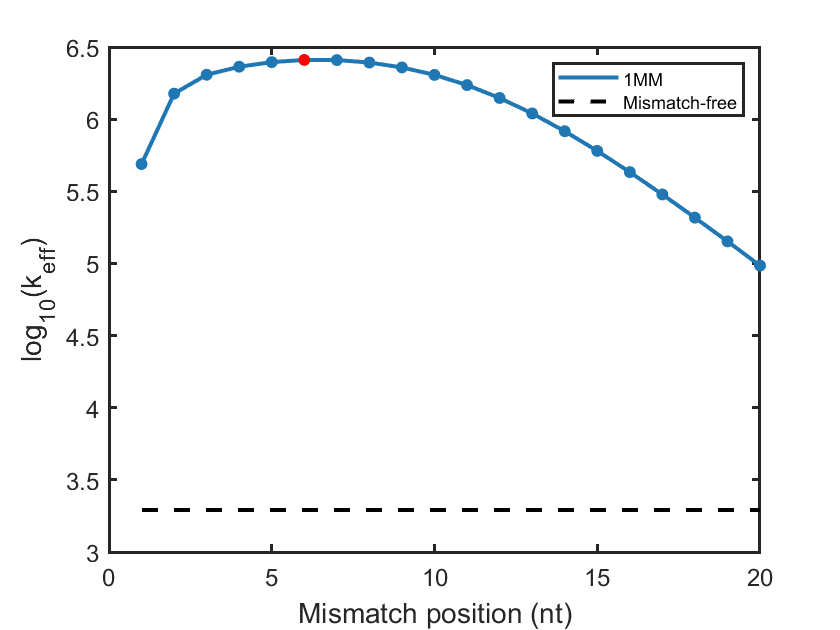

xlabel('Mismatch position (nt)', 'FontSize', 14)
ylabel('log_1_0(k_e_f_f)', 'FontSize', 14)
legend('1MM', 'Mismatch-free')
hold off 